clc; close all; clear all;

%% =============================================
%  PARAMETERS
%% =============================================
p.m = 0.1;
p.M = 0.427;
p.l = 0.10382;
p.g = -9.81;

J_true = 8.9432e-4;
b_true = 0.35;

%% =============================================
%  BUILD MODEL 1: No Friction (b = 0)
%% =============================================
alpha1 = p.m + p.M - (p.m^2 * p.l^2) / (J_true + p.m * p.l^2);
beta1  = (J_true + p.m * p.l^2) - (p.m^2 * p.l^2) / (p.m + p.M);

A1 = [0 1 0 0;
      0,  0,                -(p.m^2 * p.l^2 * p.g)/(alpha1*(J_true + p.m*p.l^2)), 0;
      0 0 0 1;
      0,  0,                 (p.m * p.g * p.l)/beta1, 0];

B1 = [0; 1/alpha1; 0; -(p.m*p.l)/beta1*(p.m+p.M)];
C  = [1 0 0 0; 0 0 1 0];
D  = [0; 0];

sys_no_friction = ss(A1, B1, C, D);

%% =============================================
%  BUILD MODEL 2: With Friction (b = 0.35)
%% =============================================
alpha2 = alpha1;   % alpha/beta don't depend on b
beta2  = beta1;

A2 = [0 1 0 0;
      0, -b_true/p.M,          -(p.m^2 * p.l^2 * p.g)/(alpha2*(J_true + p.m*p.l^2)), 0;
      0 0 0 1;
      0,  b_true/(p.M*p.l),     (p.m * p.g * p.l)/beta2, 0];

B2 = [0; 1/alpha2; 0; -(p.m*p.l)/beta2*(p.m+p.M)];

sys_friction = ss(A2, B2, C, D);

%% =============================================
%  LOAD MEASURED DATA
%% =============================================
data = readmatrix('Control2_ParameterTest.xlsx');

Ts          = data(2,1) - data(1,1);   % Auto-detect sample time from data
time_meas   = data(1:50, 1);
n_samples   = length(time_meas);

angle_20 = data(1:50, 3);
angle_50 = data(1:50, 6);
angle_80 = data(1:50, 9);
% Check what units your angle is in
angle_20 = deg2rad(angle_20);
angle_50 = deg2rad(angle_50);
angle_80 = deg2rad(angle_80);
%% =============================================
%  DEFINE PWM → INPUT AMPLITUDE MAPPING
%  Adjust scale_factor to match your hardware units
%% =============================================
scale_factor = 0.01;   % <-- Tune this to convert PWM to Newtons/Volts

pwm_vals   = [20, 50, 80];
amp_vals   = pwm_vals * scale_factor;
meas_theta = {angle_20, angle_50, angle_80};
colors     = {'b', 'r', [0.1 0.6 0.1]};

%% =============================================
%  SIMULATE & PLOT COMPARISON
%% =============================================
%% =============================================
%  SIMULATE & PLOT COMPARISON
%% =============================================
t_meas = time_meas;          % Original coarse time from Excel
%% --- Auto scale_factor per PWM ---
% Simulate model with unit amplitude, measure its peak theta output,
% then scale to match measured peak

Ts_sim  = 0.001;
t_sim   = (t_meas(1) : Ts_sim : t_meas(end))';


for i = 1:3
    % Estimate frequency from measured data
    N     = length(t_meas);
    Y_fft = fft(meas_theta{i});
    f_vec = (0:N-1) / (N * Ts);
    [~, idx] = max(abs(Y_fft(2:floor(N/2))));
    omega_est = 2 * pi * f_vec(idx + 1);

    % Simulate with unit amplitude input first
    u_unit = sin(omega_est * t_sim);
    y1_unit = lsim(sys_no_friction, u_unit, t_sim);
    y2_unit = lsim(sys_friction,    u_unit, t_sim);

    theta1_unit = interp1(t_sim, y1_unit(:,2), t_meas);
    theta2_unit = interp1(t_sim, y2_unit(:,2), t_meas);

    % Compute scale to match measured peak
    scale1 = max(abs(meas_theta{i})) / max(abs(theta1_unit));
    scale2 = max(abs(meas_theta{i})) / max(abs(theta2_unit));

    fprintf('PWM %d — scale (b=0): %.4f | scale (b=0.35): %.4f\n', ...
            pwm_vals(i), scale1, scale2);

    % Apply scale
    theta_no_fric  = scale1 * theta1_unit;
    theta_friction = scale2 * theta2_unit;

    % RMSE
    rmse1 = rad2deg(sqrt(mean((meas_theta{i} - theta_no_fric).^2)));
    rmse2 = rad2deg(sqrt(mean((meas_theta{i} - theta_friction).^2)));
    % Plot
    subplot(3,1,i);
    plot(t_meas, rad2deg(meas_theta{i}),  'k',  'LineWidth', 2.0, 'DisplayName', 'Measured'); hold on;
    plot(t_meas, rad2deg(theta_no_fric),  '--', 'Color', colors{i}, 'LineWidth', 1.5, ...
         'DisplayName', sprintf('Model (b=0),    RMSE=%.4f deg', rmse1));
    plot(t_meas, rad2deg(theta_friction), ':',  'Color', [0.8 0.3 0], 'LineWidth', 1.5, ...
         'DisplayName', sprintf('Model (b=0.35), RMSE=%.4f deg', rmse2));

    title(sprintf('Pendulum Angle \\theta — PWM = %d', pwm_vals(i)));
    xlabel('Time (s)'); ylabel('\theta (deg)');
    legend('Location', 'best'); grid on;
end

PWM 20 — scale (b=0): 5.1877 | scale (b=0.35): 1.7731
PWM 50 — scale (b=0): 10.5722 | scale (b=0.35): 3.9004
PWM 80 — scale (b=0): 14.7874 | scale (b=0.35): 5.4556


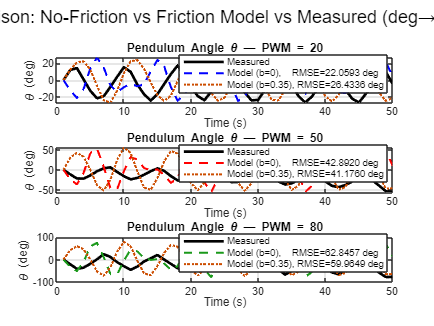

sgtitle('Theta Comparison: No-Friction vs Friction Model vs Measured (deg→rad converted)');

%% =============================================
%  PRINT RMSE SUMMARY TABLE
%% =============================================
fprintf('\n====== RMSE Summary ======\n');


====== RMSE Summary ======


fprintf('%-10s %-20s %-20s\n', 'PWM', 'RMSE (b=0)', 'RMSE (b=0.35)');

PWM        RMSE (b=0)           RMSE (b=0.35)       


fprintf('%s\n', repmat('-', 1, 52));

----------------------------------------------------



for i = 1:3
   % --- Safe frequency estimation via FFT ---
N     = length(t_meas);
Y_fft = abs(fft(meas_theta{i}));
Y_fft(1) = 0;                          % Remove DC component

half_N    = floor(N/2);
Y_half    = Y_fft(1:half_N);           % Only positive frequencies
f_vec     = (0:half_N-1) / (N * Ts);  % Matching frequency axis

[~, idx]  = max(Y_half);              % idx is now safely within f_vec
omega_est = 2 * pi * f_vec(idx);

fprintf('PWM %d — Estimated freq: %.4f Hz (%.4f rad/s)\n', ...
        pwm_vals(i), f_vec(idx), omega_est);
end

PWM 20 — Estimated freq: 0.1200 Hz (0.7540 rad/s)
PWM 50 — Estimated freq: 0.1400 Hz (0.8796 rad/s)
PWM 80 — Estimated freq: 0.1400 Hz (0.8796 rad/s)
